# Pole Placement and Luenberger Observer design for the rotary inverted pendulum - Workbook Approach + Luenberger Observer

## System Data

clear 
close all 
close all

% data for simscape model
% Run this block to initialise simscape pendulum model parameters

% Initial pendulum intial angle in degrees
% 180 corresponds to upright position
% can also be selected in the simulink model
alpha_0=170;

parametri = 1;      % 0 = nominali; 1 = identificati

%% System parameters
if parametri == 0
    B_p = 0.0024; % Pendulum viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    B_r = 0.0024; % Rotary arm viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    J_a = 0.0020; % Rotary arm moment of inertia about pivot m^2
    J_p = 0.0012; % Pendulum moment of intertia about center of mass Kg*m^2
    l_p = 0.156;  % Distance from pivot to center of mass m
    m_p = 0.127;  % Mass of pendulum Kg
    r = 0.216;    % Rotary arm length from pivot to tip m
    J_T = (J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p);
    g = 9.81;     % gravitational acceleration m/s^2

    K_g = 70;      % High-gear total gear ratio
    R_m = 2.6;     % Ohm
    eta_g = 0.90;  % Gearbox efficiency
    eta_m = 0.69;  % Motor efficiency
    k_m = 7.68e-3; % Motor back-emf constant V/(rad/s)
    k_t = 7.68e-3; % Motor current-torque constant N*m/A
else
    % Valori identificati
    load("th_id.mat")
    B_p = id_param(1); % Pendulum viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    B_r = id_param(2); % Rotary arm viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    J_a = id_param(3); % Rotary arm moment of inertia about pivot m^2
    J_p = id_param(4); % Pendulum moment of intertia about center of mass Kg*m^2
    l_p = id_param(5);  % Distance from pivot to center of mass m
    m_p = id_param(6);  % Mass of pendulum Kg
    r = id_param(7);    % Rotary arm length from pivot to tip m
    J_T = (J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p);
    g = id_param(8);     % gravitational acceleration m/s^2

    K_g = id_param(9);      % High-gear total gear ratio
    R_m = id_param(10);     % Ohm
    eta_g = id_param(11);  % Gearbox efficiency
    eta_m = id_param(12);  % Motor efficiency
    k_m = id_param(13); % Motor back-emf constant V/(rad/s)
    k_t = id_param(14); % Motor current-torque constant N*m/A
end

voltage_max = 10;
theta_max = 45;     % Maximum theta rotation[deg]
alpha_max = 15;     % Maximum alpha deflection [deg]



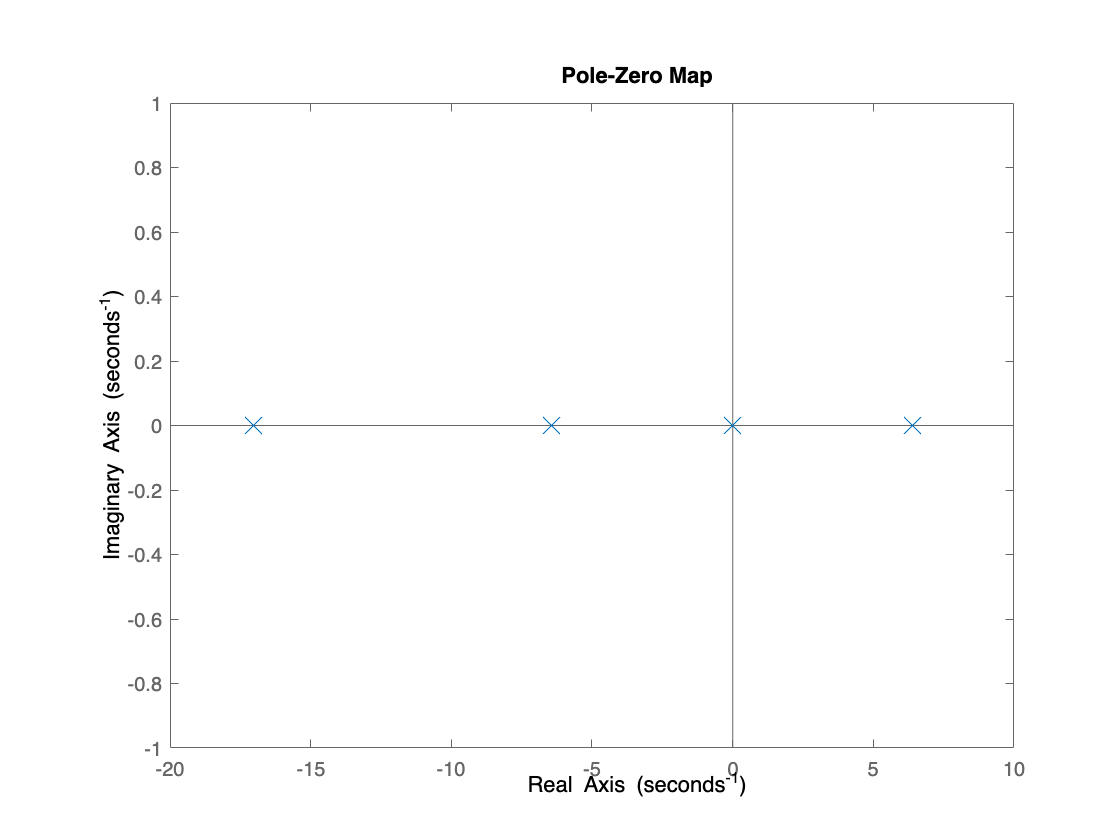

[A,B,C,D] = SS_Matrices_Voltage_Unstable(B_p,B_r,J_T,J_a,J_p,K_g,R_m,eta_g,eta_m,g,k_m,k_t,l_p,m_p,r);
sys_ol = ss(A,B,C,D); % open loop system
figure(1);
pzmap(sys_ol)
set(findobj(gca, 'type', 'line'), 'MarkerSize', 12);

poli = pole(sys_ol)

poli =          0
    6.4075
   -6.4233
  -17.0228


zeri = tzero(sys_ol)


zeri =

  0×1 empty double column vector



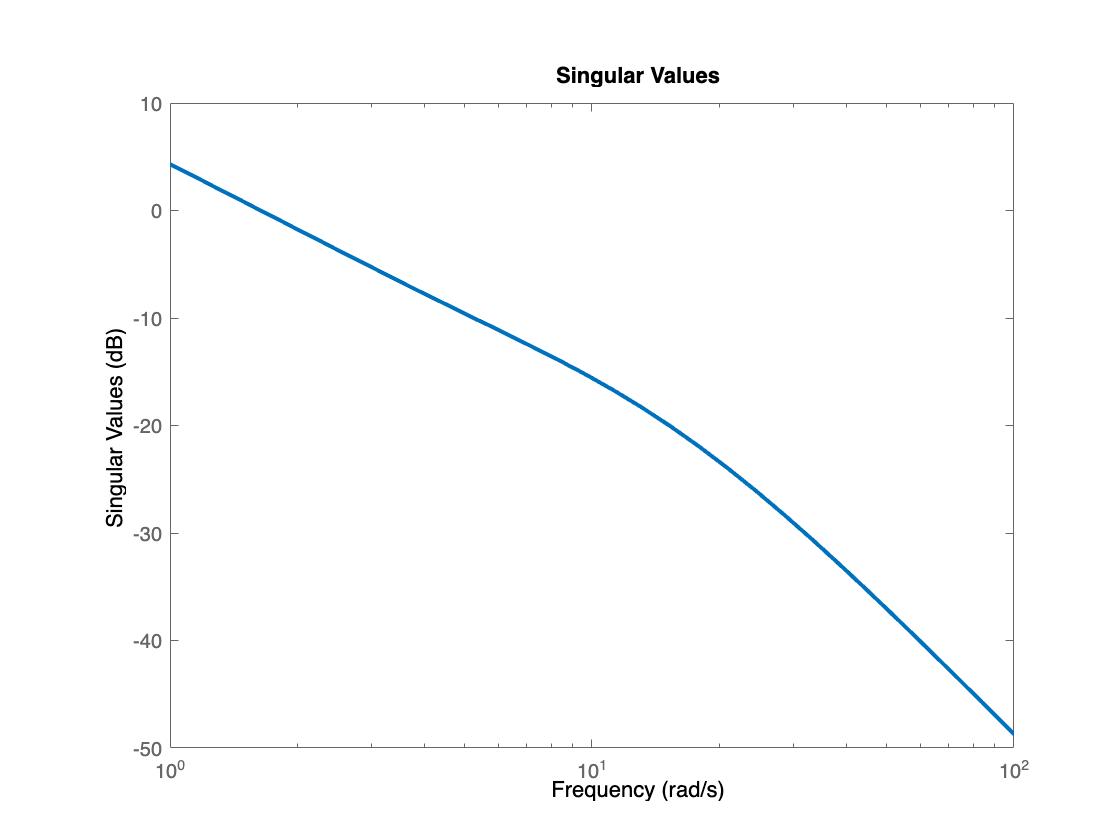

figure(2);
sigma(sys_ol); % this command is needed to plot singular values
set(findobj(gca, 'type', 'line'), 'LineWidth', 2);

## Pole Placement Controller Design

% Compute the reachability matrix for the pair (A, B)
n = 4; % order of the system 
m = 1; % input dimension
p = 2; % measured_output dimension
M_r = ctrb(A, B);  % this function computes the reachabiltiy matrix of the system
rank(M_r) == n % we compute the rank of Mr and compare it to the order of the system -> number of states

ans = logical
   1


pp_desired_poles = [0 -6.4075 -6.4233 -17.0228];
Kpp = place(A, B, pp_desired_poles)

Kpp =          0   12.4120   -1.2135    1.8033


% Compute the osservability matrix
M_o = obsv(A, C);
rank(M_o) == n

ans = logical
   1


obsv_poles = [-10 -20 -30 -40];
L_obs = place(A', C', obsv_poles)'

L_obs =    32.9488    4.0464
    9.0913   50.0126
   21.2690   27.2037
  177.9051  495.0061


A_ob = A - L_obs*C;
B_ob = [B - L_obs*D, L_obs];
C_ob = eye(n);
D_ob = zeros(n, m+p);

% DC Motor Parameters
% kt=k_t;% torque constant
% km=k_m;% motor back-emf constant
% R = R_m;% terminal resistance
% L = 0.18e-3;% terminal inductance
% 
% % Inverted Pendulum Parameters
% % lengths are in cm and mass in kg
% base_size=7; % length of pendulum base cube
% % Rotary arm parameters
% rod_rad=1;% rotary arm radius
% rod_length=21.6;% rotary arm length
% rod_mass=0.257;% rotary arm mass
% % Pendulum parameters
% p_rad=1;% pendulum radius
% p_length=33.7;% pendulum length
% p_mass=m_p;% pendulum mass
% rt1=base_size/2;
% rt2=rod_length-0.4;
% rt4=p_length/2;
% D_r=B_r;
% D_p=B_p;
